# Varmelegeme målinger

T = readtable("varmelegeme_maalinger.xlsx");

## I sekunder

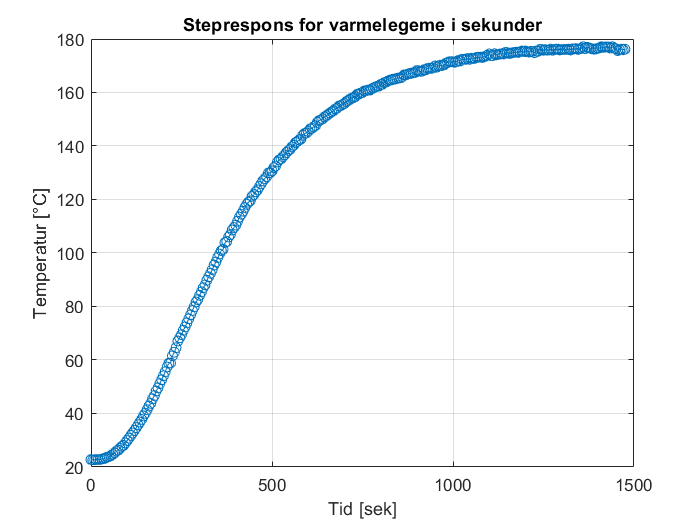

plot(T.Tid60,T.Temp60,'-o')
xlim([0,1500]);
title('Steprespons for varmelegeme i sekunder');
xlabel('Tid [sek]');
ylabel('Temperatur [°C]');
grid on;

## I minutter

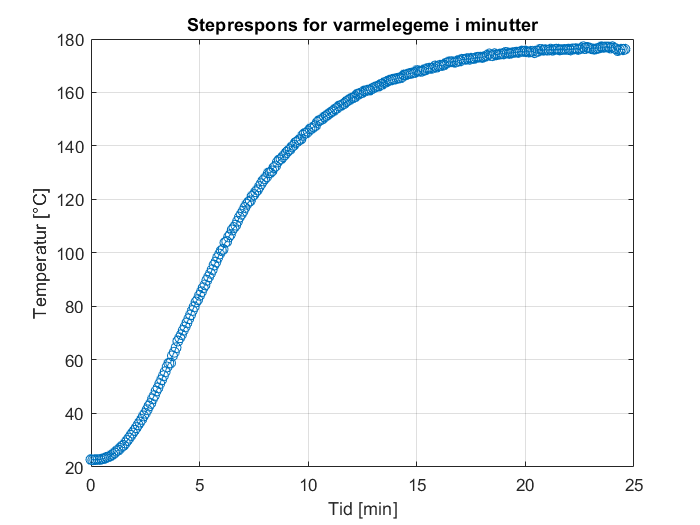

plot((T.Tid60/60),T.Temp60,'-o')
xlim([0,25]);
title('Steprespons for varmelegeme i minutter');
xlabel('Tid [min]');
ylabel('Temperatur [°C]');
grid on;

## Databehandling

Data = T.Temp60;
Tid = T.Tid60;

step = stepinfo(Data,Tid)

step = struct with fields:
        RiseTime: 622.6923
    SettlingTime: 1.0808e+03
     SettlingMin: 160.9000
     SettlingMax: 177.1000
       Overshoot: 0.5108
      Undershoot: 0
            Peak: 177.1000
        PeakTime: 1360


settl = round(step.SettlingTime/5)*5;
settlss = Data(settl/5:end,1);
steadystate = mean(settlss)

steadystate = 175.6370

## Sammenligning af data målinger

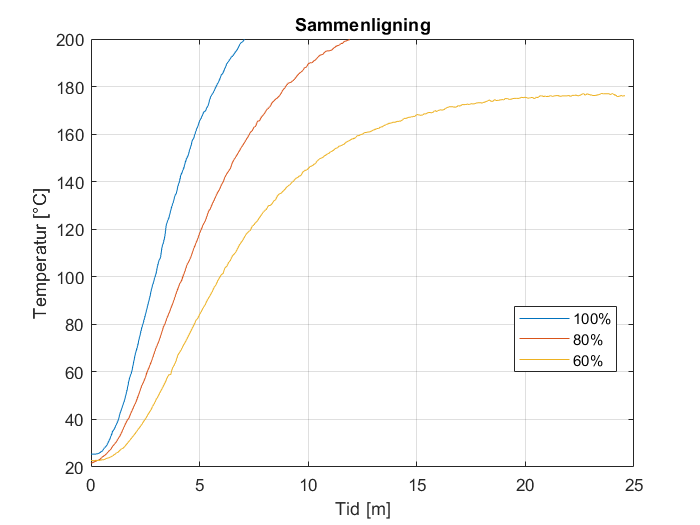

plot((T.Tid100)/60,T.Temp100);
hold on; grid on;
plot((T.Tid80)/60,T.Temp80);
plot((T.Tid60)/60,T.Temp60);
title('Sammenligning');
xlabel('Tid [m]');
ylabel('Temperatur [°C]');
legend('100%','80%','60%','Location',"best");
hold off;

## Steady-State forudsigelse

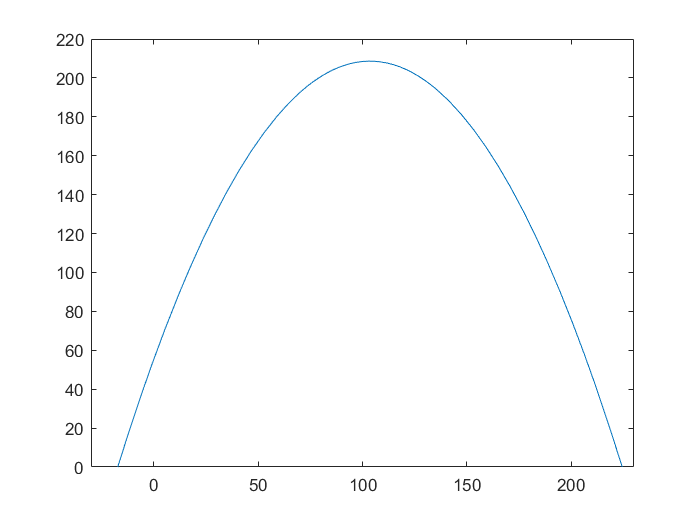

syms x;
y = (-0.0143*x^2)+(2.9623*x)+(55.205); % Tendens fra Excel

fplot(y)
xlim([-30 230])
ylim([0 220])


h = eval(solve(diff(y)== 0));

max = eval(subs(y,x,h))

max = 208.6180